#  Bayesian Inversion

close all; clear; clc;

tic
rng(1, "twister");

#### Model erstellen

Zunächst wird die Profilauslage *AB *implementiert und sowohl das synthetische Modell, als auch das Startmodell initialisiert. Die Schichtmächtigkeiten sind fixiert.

% Profile
AB = [1, 1.3, 1.8, 2.4, 3.2, 4.2, 5.6, 7.5, ...
        10, 13, 18, 24, 32, 42, 56, 75, ...
        100, 130, 180 240 320 420 560 750];

% Set up model
Hom.rho = [100 100 100 1000 1000];
Hom.thk = [1 5 5 10];
Het.rho = [100 50 50 1500 2000];
Het.thk = [1 5 5 10];
len_split = length(Hom.rho);

#### Vorwärtsrechnung

Messdaten werden durch erste Vorwärtsrechnung generiert und verrauscht.

% Add random noise
Het.rhoa = dcfwdf(Het.rho, Het.thk, AB);

% Noise type: 
% 1: additive noise, 2: relative noise, 3: superposition 
noise_type = 2;

switch noise_type
    case 1
        % Additive noise
        noise = 3;
        Het.rhoa_n = Het.rhoa + noise .* randn(size(Het.rhoa));
        sigma = noise; 
    case 2
        % Relative noise
        noise = 0.03;
        Het.rhoa_n = Het.rhoa .* (1 + noise * randn(size(Het.rhoa)) );
        sigma = noise; 
    case 3
        % Superposition relativ and additive
        noise = 0.03;
        noise_g = 0.003;
        noise_geo = noise_g * AB + zeros(size(AB));
        Het.rhoa_nn = Het.rhoa .* (1 + noise * randn(size(Het.rhoa)) );
        Het.rhoa_n = Het.rhoa_nn + noise_geo' .* randn(size(Het.rhoa));
        sigma = noise; 
end

% Number of observations
nn = length(Het.rhoa_n);

#### MCMC-Algorithmus

Schrittweite* s *und die *burn *Anzahl werden festgelegt. Der burn Wert kann entweder nach der Berechnung der Inversion visuell gewählt werden oder ca. 10 % der gesamten Iterationsanzahl n betragen. Zuätzliche werden leere Arrays initialisiert.

% Number iterations
n = 39000; 

% Burn 
burn = 3000;

% Standard deviation of normal proposal density and step size
s = 0.01; 

% Random walk
target = zeros(len_split, n);
target(:,1) = Hom.rho;
result.layer = zeros(n-1, len_split);
result.stat = zeros(n-1, 2);
proposed_log_rho = zeros(1,len_split);

% Auxiliary variable
rhoa_bestmodell = zeros(nn, 20);
modell = zeros(len_split, 20);
mittelA = 0;
prio_hist = zeros(1, 10000);

#### Metropolis-Hasting-Implementation

Der Kern des MH Algorithmus befindet sich in der for-Schleife, die bei dem Index i=2 beginnt und endet bei der Gesamtzahl von Iterationen n.

Im gesamten Algorithmus werden die Widerstandswerte logarithmiert, um numerische Rundungsfehler zu minimieren. Zunächst wird der vorherige Wert der Markow Kette der aktuellen Variablen x_i zugeordnet. Im ersten Durchlauf der Schleife ist dies der Startwert.

Auf diesen Wert aufbauend wird ein neuer Vorschlagskandidat x_prop generiert.

Die Berechnung der Likelihood *Log_Like *erfolgt durch den eindimensionalen Gauß-Prozess, die einen Mittelwert $\mu
$ und ene Standardabweichung $\sigma$ am Punkt x_i besitzt:


$$f(x| \mu, \sigma²) = \prod_{i=1}^n  \ \frac{1}{\sqrt{2\pi \sigma²}} \ \exp \left( - \frac{1}{2\sigma²} (x_i - \mu )²  \right)$$


Aufgrund numerischer Stabilität wird mit der Log-Likelihood gearbeitet.

Um die Berechnungszeit zu verkürzen, wird die Variable *hlp_time *eingeführt. Wenn der vorgeschlagene Wert nicht akzeptiert wird und die Markow Kette in demselben Zustand verharrt, wird *hlp_time* auf 1 gesetzt, sodass die Modellantwort fwd*_curr *und Likelihood nicht erneut berechnet werden müssen.

% Acceptance query
hlp_time = 1;

% Loop random walk
for i = 2:n
    
    % Assignement of previous position in MCMC chain
    current_log_rho = log(target(:,i-1));
    
    % Generating new candidate for random walk
    for k = 1:len_split 
        proposed_log_rho(k) = current_log_rho(k) + s*randn(1,1);
    end
         
    % Prior
    prior_prop = normpdf(proposed_log_rho, 5.5, 0.9);
    prior_curr = normpdf(current_log_rho, 5.5, 0.9);
     
    % Forward operation candidate
    fwd_prop = dcfwdf(exp(proposed_log_rho), Hom.thk, AB);

    % Likelihood candidate
    switch noise_type
        case 1
            % Additive Log-Like
            Log_Like_prop = - (1/(2*sigma^2)) * ...
                sum(((Het.rhoa_n)/1 - (fwd_prop)/1).^2);
        case 2
            % Relative Log-Like
            Log_Like_prop = - sum(log(fwd_prop)) - (1/(2*sigma^2)) * ...
                sum((Het.rhoa_n - fwd_prop).^2 ./ fwd_prop.^2);
        case 3
            % Superposition
            Log_Like_prop = - sum(log(fwd_prop * noise + noise_geo')) - ...
                0.5 * sum((Het.rhoa_n - fwd_prop).^2 ./ ...
                (fwd_prop.^2 * noise^2 + noise_geo'.^2));
    end
    
    % Forward operation and likelihood, if previous step was accepted
    if hlp_time == 1  
        % Forward operation
        fwd_curr = dcfwdf(exp(current_log_rho), Hom.thk, AB);
        
        % Likelihood
        switch noise_type
            case 1
                % Additive Log-Like
                Log_Like_curr = - (1/(2*sigma^2)) * ...
                    sum(((Het.rhoa_n)/1 - (fwd_curr)/1).^2);
            case 2
                % Relative Log-Like
                Log_Like_curr = - sum(log(fwd_curr)) - (1/(2*sigma^2)) * ...
                    sum((Het.rhoa_n - fwd_curr).^2 ./ fwd_curr.^2); 
            case 3
                % Superposition
                Log_Like_curr = - sum(log(fwd_curr * noise + noise_geo')) - ...
                    0.5 * sum((Het.rhoa_n - fwd_curr).^2 ./ ...
                    (fwd_curr.^2 * noise^2 + noise_geo'.^2));
        end 
    end
    
    % Posterior density
    post_dens = sum(log(prior_prop)) + Log_Like_prop;

    % Probability of move
    A = exp(post_dens - sum(log(prior_curr)) - Log_Like_curr); 
    
    % Generate uniformly distributed random variable
    u = rand(1,1);
    
    % Acceptance query
    if u <= min(A, 1)
        % Random walk
        target(:,i) = exp(proposed_log_rho); 
        
        % Results
        result.layer(i-1,:) = exp(proposed_log_rho);
        result.stat(i-1,1) = Log_Like_prop;
        result.stat(i-1,2) = post_dens;
        
        % Auxiliary variable
        mittelA = mittelA + 1; 
        hlp_time = 1;
    else
        % Random walk
        target(:,i) = exp(current_log_rho); 
        
        % Auxiliary variable
        hlp_time = 0;
    end
end

#### Berechnung der Akzeptanzwahrscheinlichkeit

Die Akzeptanzwahrscheinlichkeit gibt an, wie viel Prozent der vorgeschlagenen Werten vom MH Algorithmus akzeptiert worden ist. Angestrebt werden 23 %:

akwrs = (mittelA/n) * 100

akwrs = 62.3538

#### MAP-Schätzer

Um die Maximum-a-Posterioriverteilung zu berechnen, muss die Ergebnismatrix *result *nach den Wahrscheinlichkeitsdichten absteigend sortiert werden und Nulleinträge eliminiert werden.

[~, s_idx] = sort(result.stat(:, end), 'descend'); 
result.stat = result.stat(s_idx, :);  
result.layer = result.layer(s_idx, :); 

idx = find(result.stat(:,1), 1);
result.stat = result.stat(idx:end, :);
result.layer = result.layer(idx:end, :);

Für de 20 besten Ergebnisse - nach MAP-Schätzer - werden die Sondierungskurven berechnet und die Widerstände der Matrix *model_map* zugeordnet.

map_n = 20;
model_map = zeros(len_split, map_n);
for i = 1:map_n 
    rhoa_bestmodell(:,i) = dcfwdf(result.layer(i,:), Het.thk, AB);
    model_map(:,i) = result.layer(i,:);
end

Auf Grundlage dieser Matrix *model_map* werden Mittelwert, Standardabweichung, Varianz und 5 Quantile berechnet. 

model_mean = mean(model_map,2);
model_var = var(model_map,0,2);
model_std = std(model_map,0,2);
model_stat = [1./model_mean 1./model_std];

rho_quant = quantile(model_map,[0.025 0.25 0.50 0.75 0.975],2);

#### Mittelwertberechnung

Hier wird eine andere Berechnungsart gewählt, um das geeignetste Modell zu rekonstruieren. Mittelwert, Standardabweichung, Varianz und 5 Quantile werden über die gesamte Kette, ausgenommen der Aufwärmphase, berechnet.

model_mean2 = mean(target(:,burn:end),2);
model_var2 = var(target(:,burn:end),0,2);
model_std2 = std(target(:,burn:end),0,2);
model_stat2 = [model_mean2 model_std2];

rho_quant2 = quantile(target(:,burn:end), [0.025 0.25 0.50 0.75 0.975],2);

% Model answer
rhoa_bestmodell2 = dcfwdf(model_mean2', Het.thk, AB);

#### Darstellung des Random Walk für jede Schicht

Für jeden Modellparameter kann der Random Walk dargestellt werden.

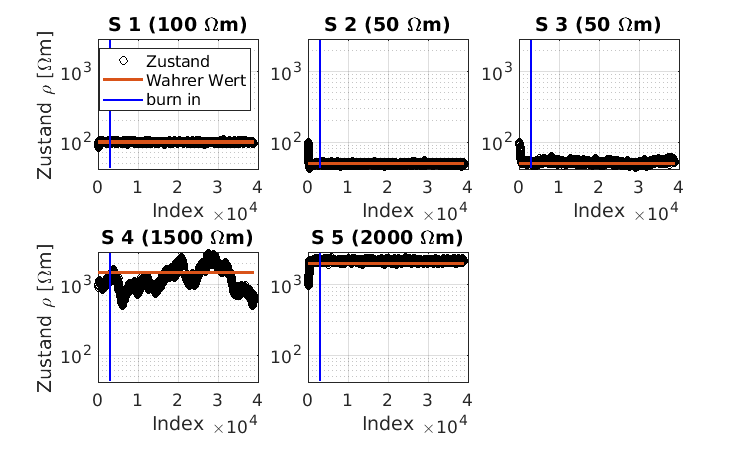

maxxi = max(target, [], 'all');
minni = min(target, [], 'all');
figure(1)
for m = 1:len_split
    subplot(2,3,m)
    plot(1:n, target(m,:), 'ko'); hold on
    plot(1:n, ones(1,n)*Het.rho(m), 'LineWidth', 2.5);
    plot([burn, burn], [minni, maxxi], '-b', 'LineWidth', 1.5);
    set(gca, 'YScale', 'log', 'Fontsize', 13)
    title("S " + m + " (" + Het.rho(m) + " \Omegam)")
    xlabel('Index')
    if m == 1 || m == 4
        ylabel('Zustand \rho [\Omegam]')
    end
    xlim([0,n+1000])
    xticks([0:10000:40000])
    ylim([40, maxxi])
    yticks(logspace(2,3,2))
    if m == 1
        legend('Zustand', 'Wahrer Wert', 'burn in')
    end
    grid on
    x0=100;
    y0=1000;
    width=750;
    height=450;
    set(gcf,'position',[x0,y0,width,height])
end

#### Darstellung der Tiefensondierung

Um die Qualität der Inversionsergebnisse zu bestimmen, werden die Modellantworten zusammen mit den Messwerten in einer Sondierungskurve visualisiert.

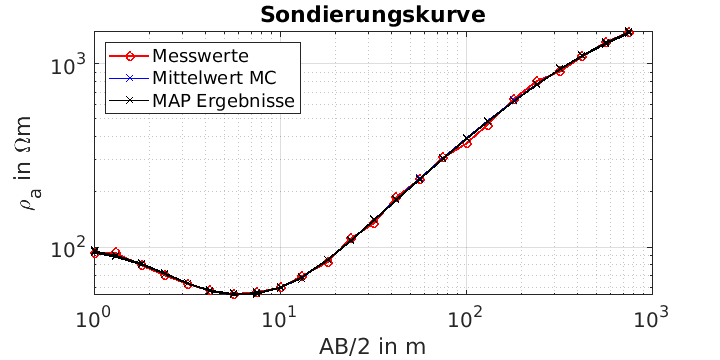

figure(2)
loglog(AB, Het.rhoa_n, 'o-r', 'LineWidth', 1.5);
hold on
loglog(AB, rhoa_bestmodell2, 'x-b', 'LineWidth', 1);
for p = 1:20
    loglog(AB, rhoa_bestmodell(:,p), 'x-k', 'LineWidth', 1);
end
set(gca, 'Fontsize', 15)
title('Sondierungskurve','FontWeight','bold')
ylabel('\rho_a in \Omegam')
xlabel('AB/2 in m')
legend('Messwerte','Mittelwert MC','MAP Ergebnisse','location','northwest')
grid on
x0=100;
y0=1000;
width=720;
height=360;
set(gcf,'position',[x0,y0,width,height])

#### Darstellung des Vergleichs Prior zu Posterior

Der direkte Vergleich der Priori mit der Posteriori Verteilung für jeden Modellparameter zeigt in welchen Bereichen die Verteilung konzentrierter geworden ist und somit eine Informationszunahme stattfand.

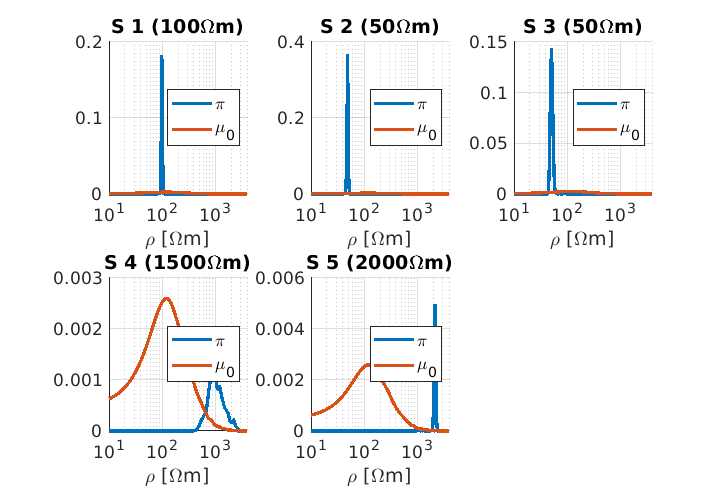

for i = 1:10000
    prio_hist(i) = lognrnd(5.5, 0.9); 
end
for k = 1:len_split
    [f(k,:), xi(k,:)] = ksdensity(target(k,:), (1:2:4000));
end

prior_histks = ksdensity(prio_hist, (1:2:4000));

figure(3)
for i = 1:5
    subplot(2,3,i)
    set(gca, 'Fontsize', 13)
    hold on
    plot(xi(1,:), f(i,:), 'LineWidth', 2.5)
    plot(xi(1,:), prior_histks, 'LineWidth', 2.5)
    set(gca, 'XScale', 'log')
    title("S " +i+ " (" + Het.rho(i) + "\Omegam)")
    xlim([10 4000])
    xticks(logspace(1,4,4))
    xlabel('\rho [\Omegam]')
    legend("\pi", "\mu_0", 'location', 'east' ,'Fontsize',13)
    grid on
    ax = gca;
    ax.YAxis.Exponent = 0;
    x0=100;
    y0=1000;
    width=720;
    height=500;
    set(gcf,'position',[x0,y0,width,height])
end

#### Tiefendarstellung

Zusätzlich kann die Darstellung der Quantile einen Überblick über Unsicherheit in jeder Schicht schaffen.

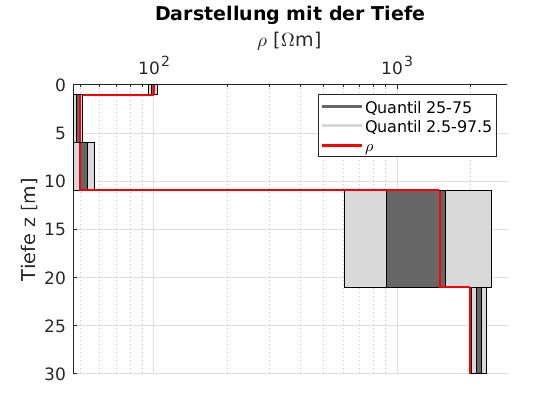

% Layer thickness
d = [1 5 5 10 9];
d_len = sum(d);

% Maximal expansion Plot
max_hlp = max(max(target(:)), 2100); 

figure(4)
set(gca, 'Fontsize', 13)
hold on

% Layer 1
rectangle('Position',[rho_quant2(1,1) 0 abs(minus(rho_quant2(1,1), ...
    rho_quant2(1,5))) 1], 'FaceColor',[0.85 0.85 0.85])
rectangle('Position',[rho_quant2(1,2) 0 abs(minus(rho_quant2(1,2), ...
    rho_quant2(1,4))) 1], 'FaceColor',[0.4 0.4 0.4])
plot(ones(1, length(0:1))*Het.rho(1), 0:1, 'r-', 'LineWidth', 1.5);
plot(50:100, ones(1, length(50:100)), 'r-', 'LineWidth', 1.5);

% Layer 2
rectangle('Position',[rho_quant2(2,1) 1 abs(minus(rho_quant2(2,1), ...
    rho_quant2(2,5))) 5], 'FaceColor',[0.85 0.85 0.85])
rectangle('Position',[rho_quant2(2,2) 1 abs(minus(rho_quant2(2,2),...
    rho_quant2(2,4))) 5], 'FaceColor',[0.4 0.4 0.4])
plot(ones(1, length(1:6))*Het.rho(2), 1:6, 'r-', 'LineWidth', 1.5);

% Layer 3
rectangle('Position',[rho_quant2(3,1) 6 abs(minus(rho_quant2(3,1), ...
    rho_quant2(3,5))) 5], 'FaceColor',[0.85 0.85 0.85])
rectangle('Position',[rho_quant2(3,2) 6 abs(minus(rho_quant2(3,2), ...
    rho_quant2(3,4))) 5], 'FaceColor',[0.4 0.4 0.4])
plot(ones(1, length(6:11))*Het.rho(3), 6:11, 'r-', 'LineWidth', 1.5);
plot(50:1500, 11*ones(1, length(50:1500)), 'r-', 'LineWidth', 1.5);

% Layer 4
rectangle('Position',[rho_quant2(4,1) 11 abs(minus(rho_quant2(4,1), ...
    rho_quant2(4,5))) 10], 'FaceColor',[0.85 0.85 0.85])
rectangle('Position',[rho_quant2(4,2) 11 abs(minus(rho_quant2(4,2), ...
    rho_quant2(4,4))) 10], 'FaceColor',[0.4 0.4 0.4])
plot(ones(1, length(11:21))*Het.rho(4), 11:21, 'r-', 'LineWidth', 1.5);
plot(1500:2000, 21*ones(1, length(1500:2000)), 'r-', 'LineWidth', 1.5);
plot(50:1500, 11*ones(1, length(50:1500)), 'r-', 'LineWidth', 1.5);

% Layer 5
rectangle('Position',[rho_quant2(5,1) 21 abs(minus(rho_quant2(5,1), ...
    rho_quant2(5,5))) 9], 'FaceColor',[0.85 0.85 0.85])
rectangle('Position',[rho_quant2(5,2) 21 abs(minus(rho_quant2(5,2), ...
    rho_quant2(5,4))) 9], 'FaceColor',[0.4 0.4 0.4])
plot(ones(1, length(21:30))*Het.rho(5), 21:30, 'r-', 'LineWidth', 1.5);

set(gca,'XAxisLocation','top')
set(gca,'YDir','reverse');
set(gca, 'XScale', 'log')
xlim([0 max_hlp])
ylim([0 d_len])
xlabel('\rho [\Omegam]')
ylabel('Tiefe z [m]')
title('Darstellung mit der Tiefe')
hline1 = line(NaN,NaN, 'LineWidth', 2, 'LineStyle', '-', ...
    'Color', [0.85 0.85 0.85]);
hline2 = line(NaN,NaN, 'LineWidth', 2, 'LineStyle', '-', ...
    'Color', [0.4 0.4 0.4]);
hline3 = line(NaN,NaN, 'LineWidth', 2, 'LineStyle', '-', 'Color', 'r');
legend([hline2, hline1, hline3], 'Quantil 25-75', 'Quantil 2.5-97.5', ...
    '\rho')
grid on

#### Zeitangabe

Hier erfolgt die Ausgabe der benötigten Berechnungszeit.

%% Time display
et = toc;
etchar = sprintf('Elapsed time: %.2f sec. \n', et);
fprintf(etchar);

Elapsed time: 4.89 sec. 


#### Speicheroption

% save('variables.mat')